# Setup the enviroment

## Create a shared session

In order to connect the C++ Application to this Matlab instance, matlab needs to be shared.

if matlab.engine.isEngineShared == 0
    matlab.engine.shareEngine('Experiment') % Used to be able to connect from the C++ application to this matlab session
end

## Create the variable S

To make it easy for building custom UTF's, S gets defined as the laplace variable.

Transfer functions then can be created using: sys = 1/S;

S=tf('s'); 


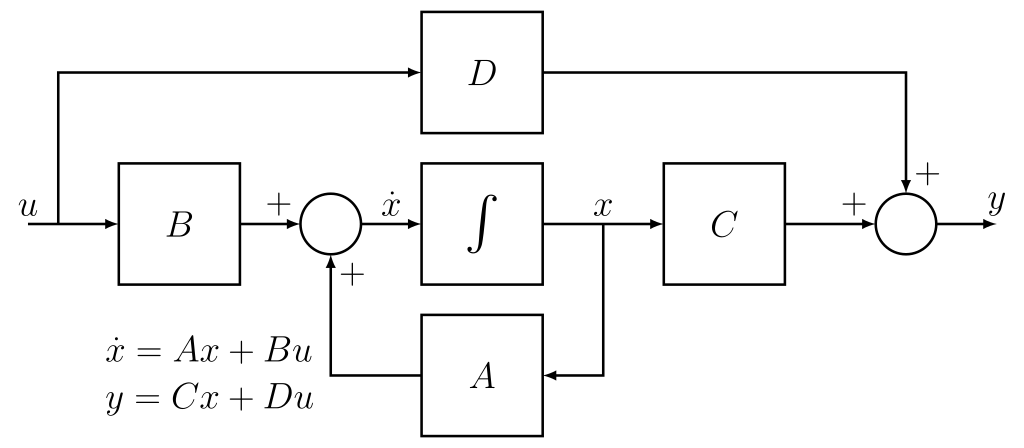

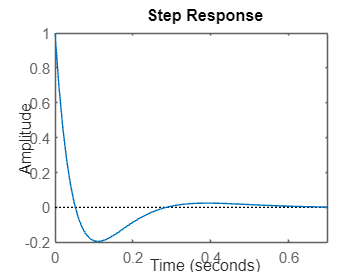


%C_base = tf([1, 2, 2], [1, 8, 8]);
N1 = (S - 0i + 1) * (S + 0i + 1);
N2 = (S - 0i + 2) * (S + 0i + 2);
N3 = (S - 0.1i + 2) * (S + 0.1i + 2);
%
C_base = N1*N2/((S+10)*(S+10)*(S+10)*(S+10)); %N1*N2*N3/( (S+4) * (S+4) * (S+4)*(S+4) * (S+4) * (S+4));
step(C_base)